Denne kode indlæser data fra svingdetektoren på bilen og laver en graf over det.

clear, close all, clc

Indlæs kommaseparerede værdier. Denne fil er skrevet vha. en ofstream i C++-programmet.

load("C:\Users\Sebastian.SEBASTIANBÆRBAR\Google Drev\2. Semester - Projekt\Bluetooth\svingdata_hhvhhh.txt")
s = svingdata_hhvhhh(1,:); %Gem alle svingdata i en vektor
t = ones(1,length(s));

for n = 1:length(t)
    t(1,n)=t(1,n)*60*n; %Gem tiden til hvert datapunkt
end

Grafen for udsvinget plottes

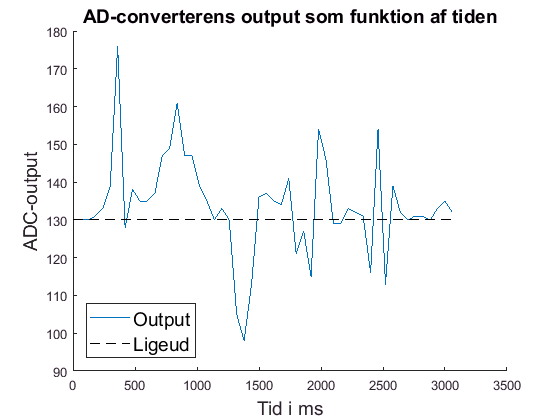

hold on
plot(t, s) %Tiden og svingene plottes

%Linje for "ligeud" plottes
plot([1:t(length(s))],[s(2)*ones(size([1:t(length(s))]))],'--k', 'LineWidth', 0.1)

%Titel, labels, legend
title('AD-converterens output som funktion af tiden', 'FontSize', 14)
xlabel('Tid i ms', 'FontSize', 14)
ylabel('ADC-output', 'FontSize', 14)
legend({'Output', 'Ligeud'}, 'Location', 'southwest', 'FontSize', 14)